# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.File = mfilename;
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Instru\RawData'];                               
Deci.SubjectList        = 'gui';
Deci.Step               =1; % Define Trial;
Deci.Proceed            =1;                          % If 0 or 1, Do you want Deci to automatically proceed to next steps? Suggest 0 for first-time users.
Deci.Layout.Noeye       = 'easycap_rob_noeye.mat';         % Layout without Ocular Channels, Default is ReinhartLab 1020 system
Deci.Layout.eye         = 'easycap_rob_binocular.mat';           % Layout with Ocular Channels
Deci.PCom               = 0;        % Activates Parallel Computing (if availible)
Deci.Debug              = 0;        % Activates dbstop if error
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Instru\ProcessedData'];     

Deci = Checkor(Deci);

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 30] [21 30] [23 30] [24 30]};   
    Deci.DT.Locks      = [14 14 14 14];     
    Deci.DT.Conditions = [1 2 3 4];         
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Beha = [];
    %Deci.DT.Beha.Acc = {[31] [31] [31] [31] [31] [31] };
    %Deci.DT.Beha.RT = {[41 30] [41 30] [41 30] [41 30] [41 30] [41 30]};

if Deci.Step <= 1
    DefineTrialor(Deci);
    if ~Deci.Proceed; return; end
end

## 2. PreProcessing Steps

####    Rereference channel to average of Implicit Electrode and Offline Reference

   Deci.PP.Imp                = 'TP10:TP9'; % 'Impicit Reference?[Implicit:RefChannels without Implicit]'
   Deci.PP.Ocu                = 'TVEOG:BVEOG,LHEOG:RHEOG';    % 'Ocular Reref?[Ref-Channels without Ref]'

#### Other Processing Steps

    Deci.PP.ScalingFactor       = [];               % Scalar, If the data needs to scale
    Deci.PP.HBP                 = [];               % Scalar,High-bandpass filter, in Hz.
    Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.
    
    Deci.PP.Repair              = [];                           % Structure, View and Repair (via interpoltation) Channels
%     Deci.PP.Repair.Type         = 'Manual';                   % String,'Manual' or 'Auto'
%     Deci.PP.Repair.Auto         = {};                         % Nx1 Subject cell array of Mx1 cells of M Channels to reject.

    Deci.PP.CleanLabels = 0; % Binary, normalize electrode names to be compatiable with Reinhart Lab's Needs.

if Deci.Step <= 2
    PreProcessor(Deci)
    if ~Deci.Proceed; return; end
end

## 3. Artifact Rejection

#### Individual Component Analysis

    Deci.Art.ICA.Reject                     = 1; % Whether or Not to do ICA
    Deci.Art.ICA.Eye.Chans           = {'BVEOG','RHEOG','AF7','AF8'}; 

#### Trial Artifacts

     Deci.Art.TR.Toi              = [-.5 -.2];          % Time Range of Interest to look for Artifacts
     %Deci.Art.TR.rToi           = [-.5 1];              % Only available for Shifts.
 
     Deci.Art.TR.Eye                  = [];               % Comment the rest of .Eye to not do Eye Artifact Trial Rejection%      Deci.Art.TR.Eye.Interactive      =  0;                % Enable Interactive Trial Artifact Rejection
     %Deci.Art.TR.Eye.Chans            = {'BVEOG','RHEOG','AF7','AF8'};    % 1xChan Cell Array of Ocular Eye Channels

    Deci.Art.TR.Muscle               = [];               % Comment the rest of .Muscle to not do Muscle Artifact Trial Rejection
    %Deci.Art.TR.Muscle.Interactive   = 0;                % Enable Interactive Trial Artifact Rejection

#### Manual Visual Artifact Rejection

    Deci.Art.Manual = [];
     %Deci.Art.Manual.Toi              = [-.5 -.2];
     %Deci.Art.Manual.rToi              =[-.5 1];  % Only available for Shifts.

if Deci.Step <= 3
    Artifactor(Deci);
    if ~Deci.Proceed; return; end
end

## 4. Analysis

#### General Set-Up

    Deci.Analysis.ArtifactReject     =1;                    % Specify whether or not to Apply Trial Rejection
    Deci.Analysis.Channels           = 'all';                % Cell array of channels or 'all'
    Deci.Analysis.Laplace            =1;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
    
    Deci.Analysis.Redefine = [];                             % Only available for Shifts.
%     Deci.Analysis.Redefine.Bsl = [-.5 -.2];
%     Deci.Analysis.Redefine.ERPToi = -.5;
    

#### Time-Frequency Analysis

    Deci.Analysis.Freq               = [];           % Comment the rest of .Freq to not do Fourier Transformation
    Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
    Deci.Analysis.Freq.foi           = exp(linspace(log(2),log(40),40));       % Frequency of Interest
    Deci.Analysis.Freq.width         = 7 ;           % Width
    Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
    Deci.Analysis.Freq.Toi           = [-.5 1];       % Time Range
    Deci.Analysis.Freq.kptrls = 0
    Deci.Analysis.Freq.Redefine = 0;   % 1 for Both BSL and Freq, or 2 just BSL % Only available for Shifts.

#### Event Related Potential Analysis

  Note that entire Time Range will be analyzed.

    Deci.Analysis.ERP                = []%  0;

#### Cross-Frequency Coupling 

            Requires* .Freq * to have been done.

    Deci.Analysis.Freq.CFC = [];
%     Deci.Analysis.Freq.CFC.chanlow = {'Fz' 'Cz'};
%     Deci.Analysis.Freq.CFC.chanhigh = {'C3' 'O1'}; %Try not to do all to all if you have more than 10 chans
%     
%     Deci.Analysis.Freq.CFC.latencyhigh = [-.5 .5]; %no implementation yet to check for edge artifactsm so be careful
%     Deci.Analysis.Freq.CFC.latencylow = [-.5 .5];
%     
%     Deci.Analysis.Freq.CFC.Freqhigh = 'beta';
%     Deci.Analysis.Freq.CFC.Freqlow = 'theta';
%     
%     Deci.Analysis.Freq.CFC.timebin = 5;
%     Deci.Analysis.Freq.CFC.methods = {'mi','plv'};  % can only currently handle 'plv' or 'mi'(pac)
%     Deci.Analysis.Freq.CFC.keeptrials =  'no';
%         
    %     cfg.method     = string, can be
    %                     'coh' - coherence [Fourier-Fourier]
    %                     'plv' - phase locking value [phase-phase of amp]
    %                     'mvl' - mean vector length [phase-amp]
    %                     'mi'  - modulation index  [phase-amp]
    %                     'cs_cc'  - circstats circular-circular [phase-phase]
    %                     'cs_cl'  - circstats circular-linear [phase-amp]

####  Not Available

    Deci.Analysis.EvokedPower        = 0; %Not Available

if Deci.Step <= 4
    Analyzor(Deci)
    if ~Deci.Proceed; return; end
end

## 5. Plotting

#### General Set-Up

    Deci.Plot.GA =  0;                       % 0 for Individual Plots, 1 for GrandAverage
    Deci.Plot.Scale = 'log';
    Deci.Plot.Save = [];
    Deci.Plot.Save.Format =  'fig';

#### Math

    Deci.Plot.Math = [];
   Deci.Plot.Math.Form = {'[x1+x2]','[x3+x4]','[x1+x4]','[x2+x3]','[x5-x6]',['x7-x8']};    % in this example sum of Cond1 and Cond3 makes Cond 5,                
    Deci.Plot.Math.Type = 1;                    % 0 = no math plots, 1 = only math plots, 2 = both math and single plots
    

#### Time-Frequency

    Deci.Plot.Freq = [];
    
    
    Deci.Plot.Freq.Plot = 1;                % 1 or 0 to do Freq Plots
    Deci.Plot.Freq.Foi = [3 24]; 
    Deci.Plot.Freq.Toi = [];
    Deci.Plot.Freq.Channel = ['Reinhart-All'];   
    Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'
     
    Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
    Deci.Plot.Freq.Roi = [];          % use 'maxmin','maxabs or [min max] to set.
    Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

    Deci.Plot.Freq.Topo = 1;
    Deci.Plot.Freq.Square = 1;
    

####   Time-Frequency Wires

    Deci.Plot.Freq.Wires = [];
%         Deci.Plot.Freq.Wires.Collapse = 'Time';        %Which Dim to Collapse 'Time' or 'Freq'
%         Deci.Plot.Freq.Wires.avgoverfreq = 'no';
%         Deci.Plot.Freq.Wires.avgovertime= 'yes';
%         Deci.Plot.Freq.Wires.frequency = [4 8];
%         Deci.Plot.Freq.Wires.latency = [.1  .5];
%         Deci.Plot.Freq.Wires.nanmean = 'no';
    

####   ERP

    Deci.Plot.ERP = []; %Not Available to plot
    %     Deci.Plot.ERP.Channel = 'all';              % Cell array of channels or 'all'

####   PRP

    
    Deci.Plot.PRP = [];                     %Requires .Freq/.ERP to be filled out
    %Power related Potential
    %Plot 1 = Collapsed-Frequency/Channel Freq.Type Data
    %plot 2 = Collapsed-Channel           ERP Data
    %plot 3 = Condition-Specific Timepoint by Timepoint Freq-ERP coorelation across subjects
    %plot 4 = Collapsed-Time/Freq/Channel Condition-Specific Subject by Subject plotted along Freq-YAxis, ERP-XAxis
    %Changes .GA into 0
    %     Deci.Plot.PRP.label = 1;                %Whether or Not to add subject info on plot 4
    %     Deci.Plot.PRP.ScatterToi = [.3 .7];     %Time range for plot 4
    

####     Cross-Frequency Coupling

    Deci.Plot.CFC = []; 
%     Deci.Plot.CFC.method = 'plv';
%     Deci.Plot.CFC.Topo = 1;
%     Deci.Plot.CFC.Square = 1;
%     Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest
    

Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of 60
Channel T8 of 60
Channel TP10 of 60
Cha

the call to "ft_selectdata" took 0 seconds
Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of

the call to "ft_selectdata" took 0 seconds
Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of

the call to "ft_selectdata" took 0 seconds
Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of

the call to "ft_selectdata" took 0 seconds
the call to "ft_selectdata" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
the call to "ft_selectdata" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
the call to "ft_selectdata" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
the call to "ft_selectdata" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
the call to "ft_selectdata" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
the call to "ft_selectdata" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds


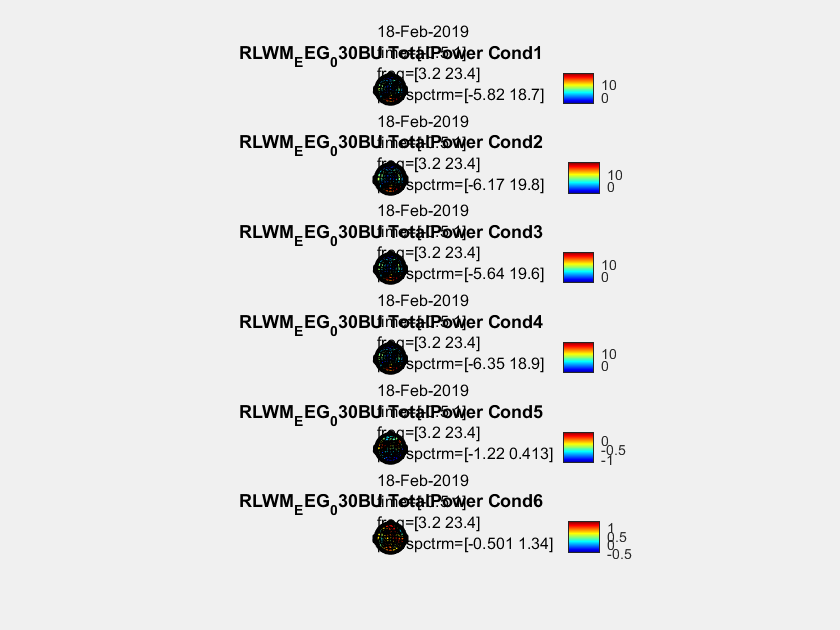

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


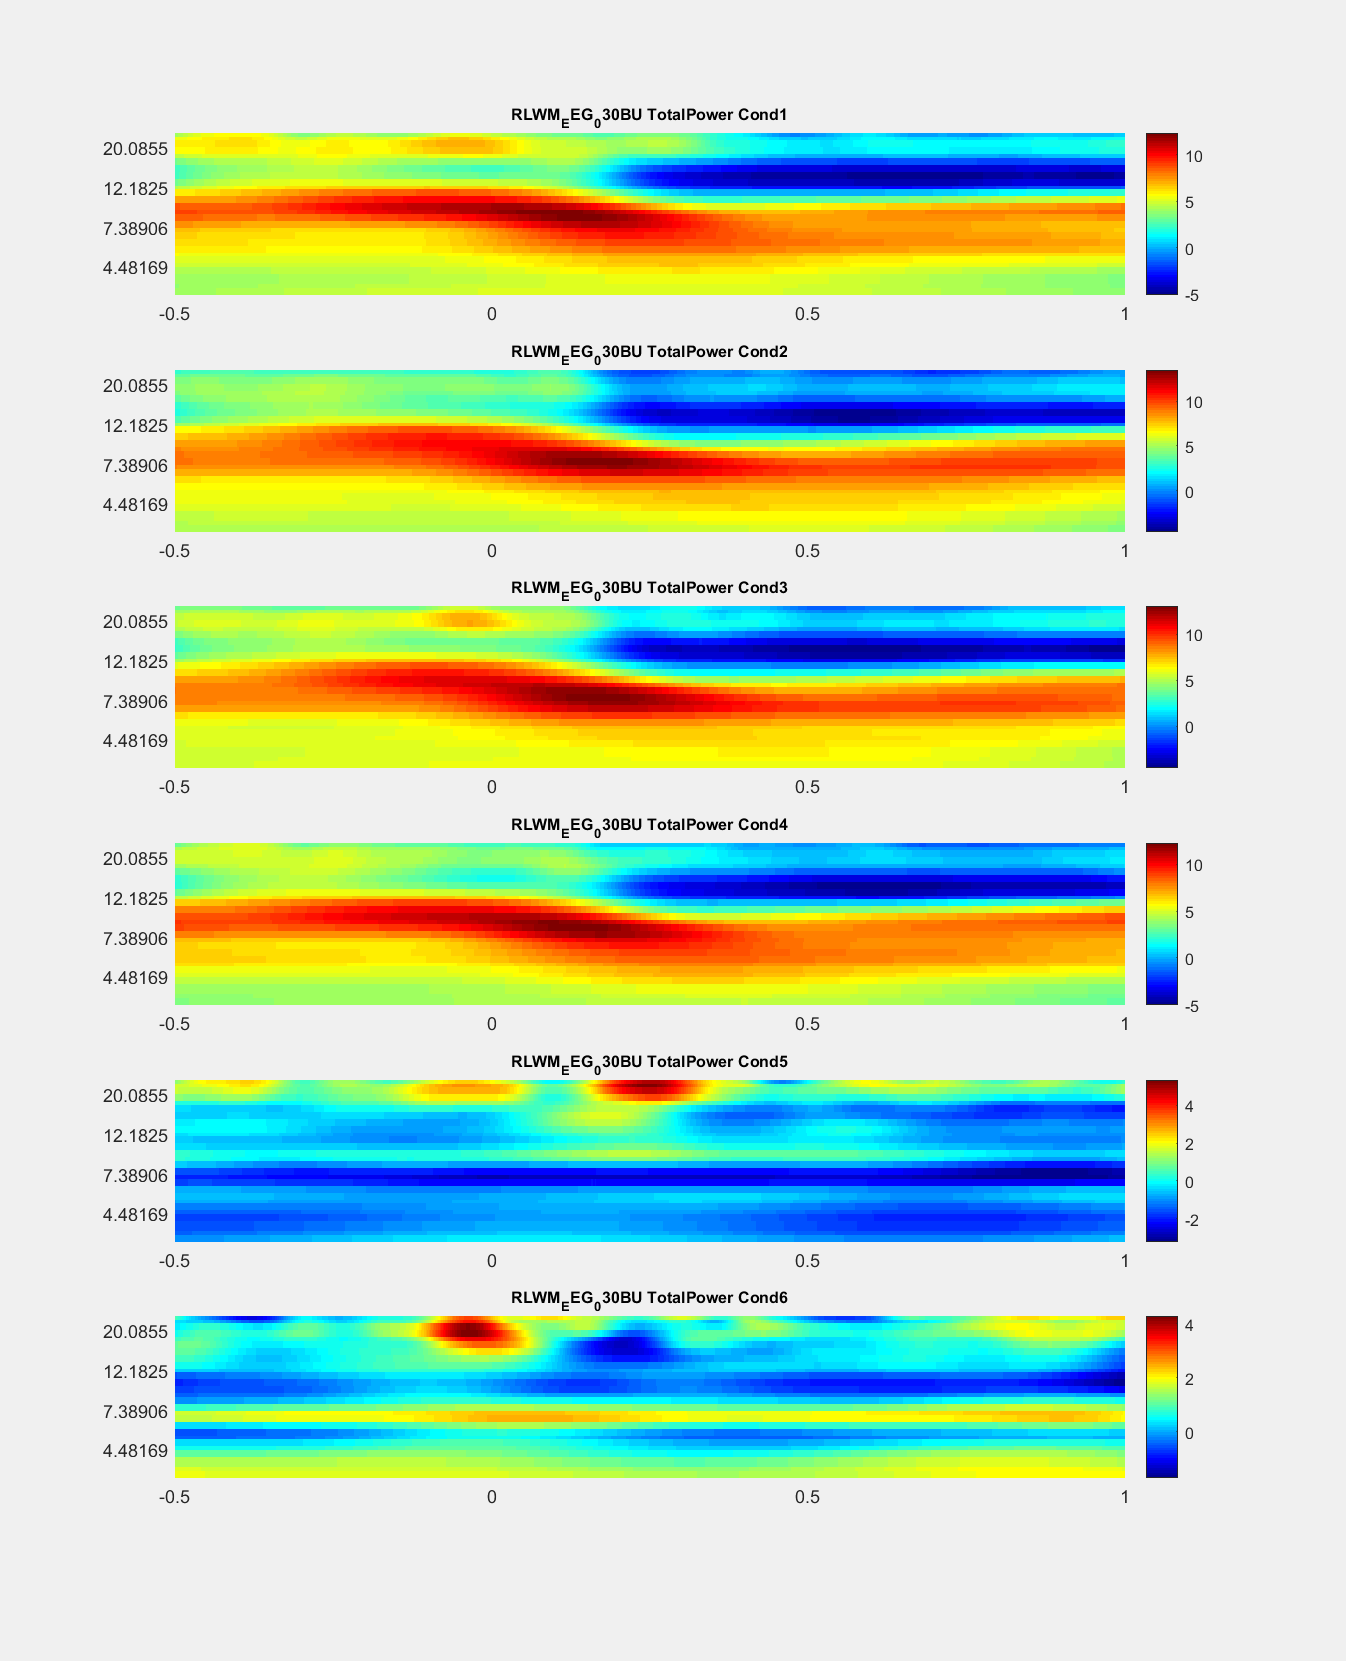

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


if Deci.Step <= 5
    Plottor(Deci);
    if ~Deci.Proceed; return; end
end